# Título: Teoría de Errores

## Introducción a Matlab

### Atajos de teclado

- `Ctrl +`: Zoom

- `Ctrl + N`: Nuevo script

- `Ctrl + S`: Guardar script

- `Ctrl + Enter`: Ejecutar una sección

### Modo de trabajo

- Guardar los scripts en uso (`error_rel.m Labo1.mlx`) en el directorio de trabajo

### Creación de funciones

- Para un ejemplo ver el script `error_rel.m`

A=1000 % valor exacto

A =         1000


a=1000.5 % valor aproximado

a =      1.000500000000000e+03


error_rel(A,a)

ans =      5.000000000000000e-04


error_relativo = error_rel(A,a)

error_relativo =      5.000000000000000e-04


### Insertando una imagen

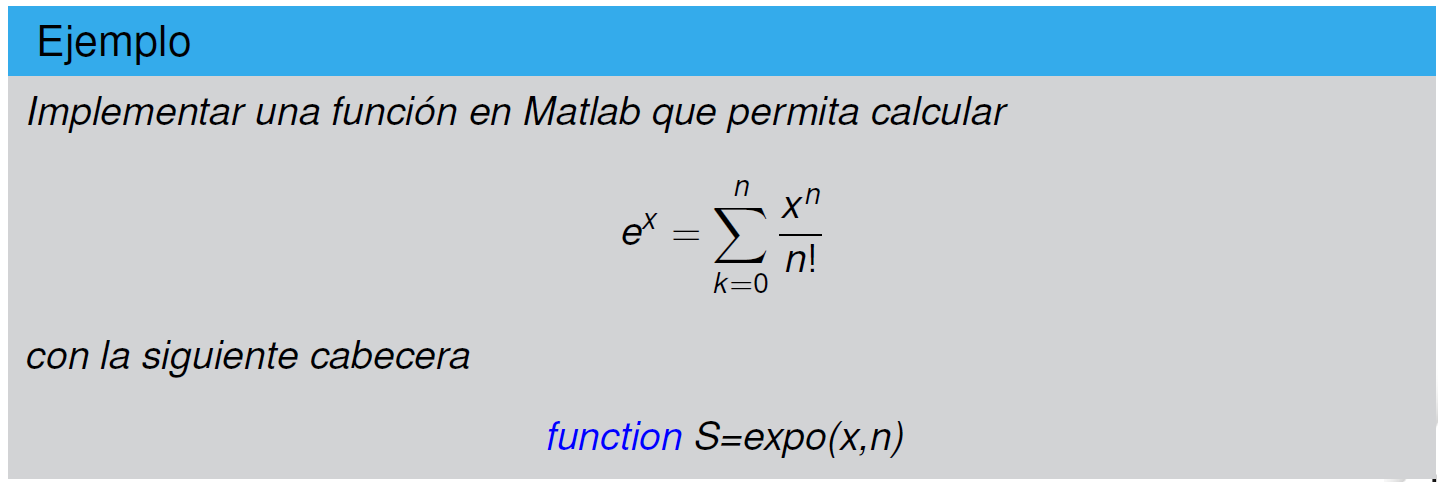

### Insertando una ecuación

`Tipear $\delta$`

genera $\delta$

Averiguar sobre **mathpix** y otras herramientas (chatGPT?)

## Teoría de Errores

Ejemplo 1


$$e^x = \sum_{k=0}^{n} \frac{x^k}{ k!}$$


x=1; n=4;
S=expo(x,n)

S =    2.708333333333333


Ejemplo 2

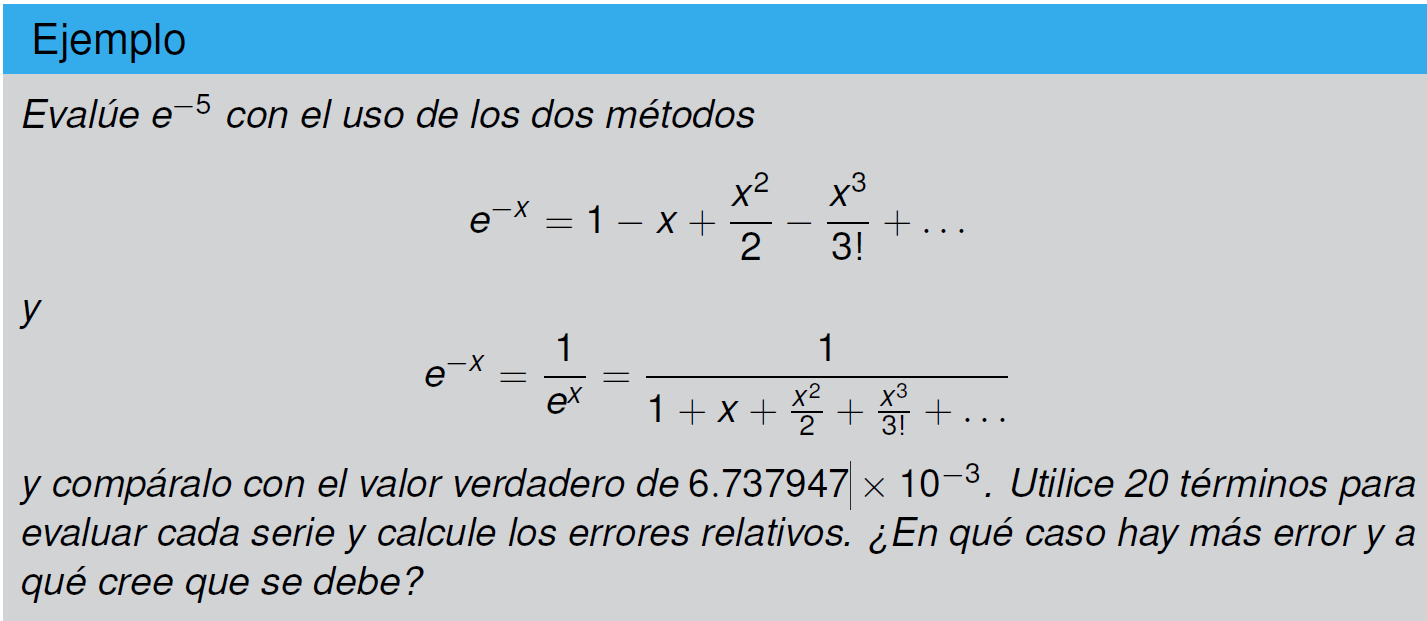

format long
valor_real = 6.737947e-3

valor_real =    0.006737947000000


aprox1 = expon(5,20) % primer caso

aprox1 =    0.006745540097712


aprox2 = 1/expo(5,20) % 20 términos

aprox2 =    0.006737947545483


error_relativo1 = error_rel(valor_real,aprox1)

error_relativo1 =    0.001126915618632


error_relativo2 = error_rel(valor_real,aprox2)

error_relativo2 =      8.095678251195621e-08


Ejemplo 3

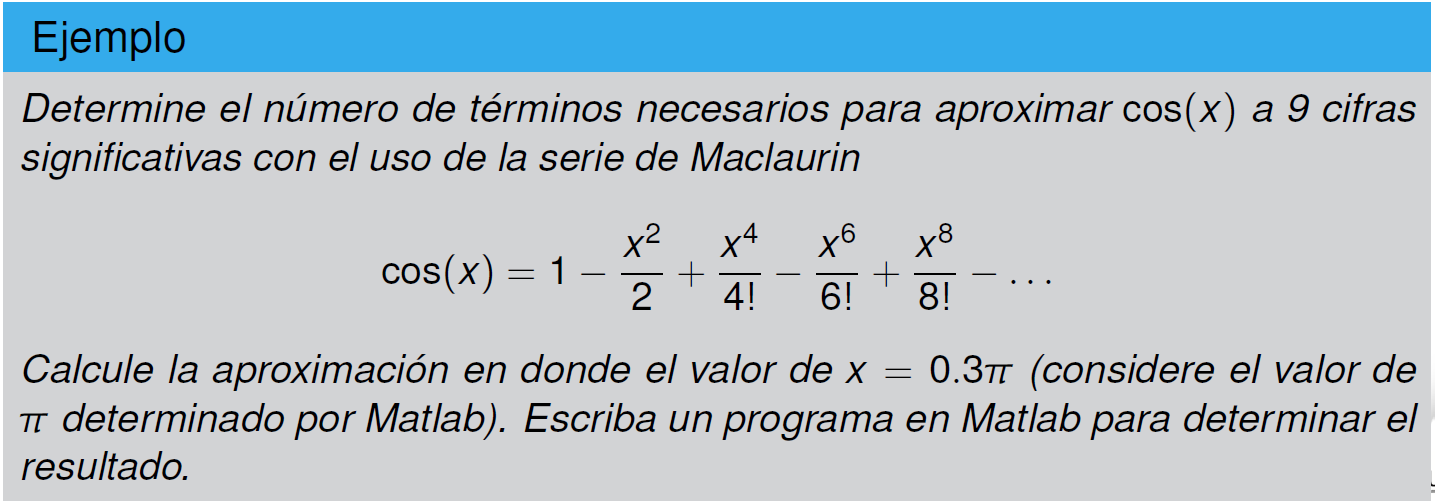

x=0.3*pi;
valor_real = cos(x) 

valor_real =    0.587785252292473


n=4; % cantidad de términos = 5
valor_aprox= fcos(x,n)

valor_aprox =    0.587785403659118


error_relativo = error_rel(valor_real,valor_aprox)

error_relativo =      2.575203169022389e-07


m=7; % número de cifras significativas
if (error_relativo <= 5*10^(-m))
    fprintf('Hay %d cifras significativas',m)
end

Hay 7 cifras significativas

Comprobar que con 6 términos en la aproximación (`n=5`) dicha aproximación tiene 9 cifras significativas (`m=9`).

Funciones definidas en este live script

function S=expo(x,n)
% Doc

% S=e^x
S=0;
for k=0:n
    % término k-ésimo
    t_k = x^k/factorial(k);
    % agregando en S
    S = S + t_k;
end

end

function S=expon(x,n)
% Doc

% S=e^(-x)
S=0;
for k=0:n
    % término k-ésimo
    t_k = (-1)^k * x^k/factorial(k);
    % agregando en S
    S = S + t_k;
end

end

function S=fcos(x,n)
% S=FCOS(x,n) devuelve el coseno de x basado en la serie
% cos(x) = 1-x^2/2+x^4/4!-x^6/6!+x^8/8!+...
% Aquí n+1 indica el número de términos empleados.
%
% Ejemplo:
% >> fcos(2,4)

% S=cos(x)
S=0;
for k=0:n
    % término k-ésimo
    t_k = (-1)^k * x^(2*k)/factorial(2*k);
    % agregando en S
    S = S + t_k;
end

end